## Práctica 3, 22 de abril de 2021

format long

Problema 1

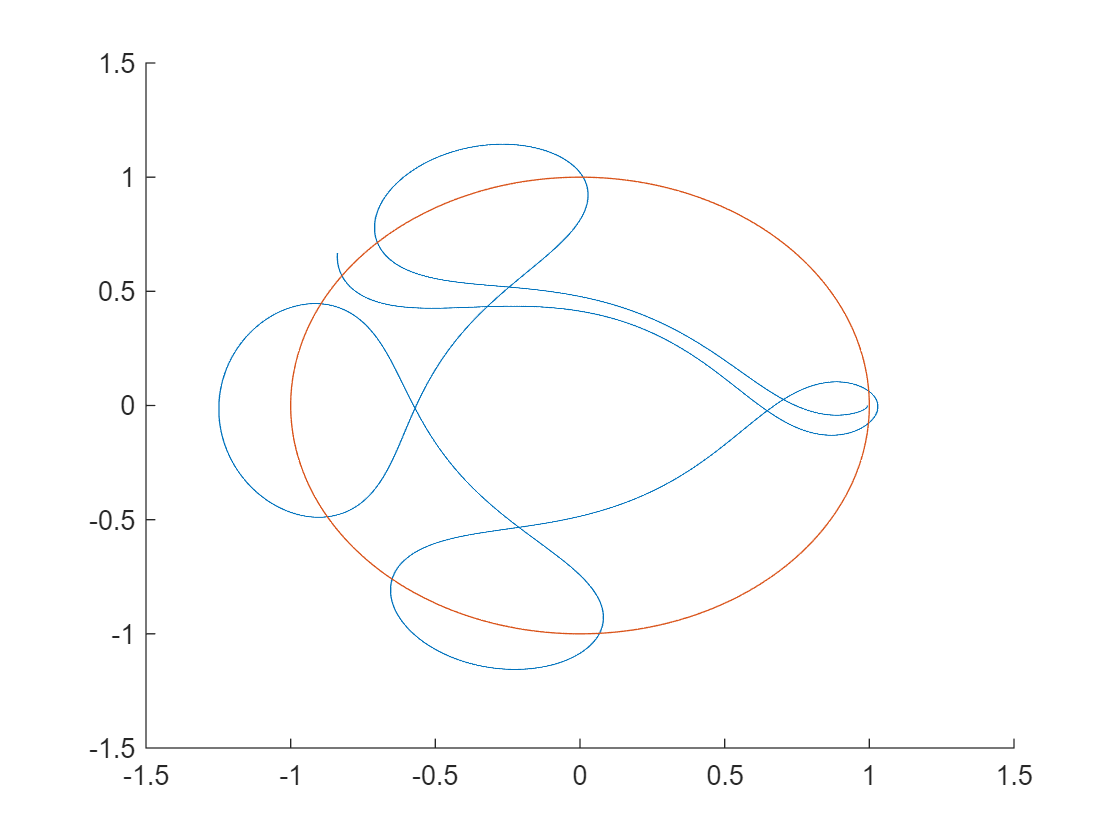

clear
%datos 
mu=0.012277471; %masa luna
mu1=1-mu; %masa de la tierra

%valores de a y b
a=0;
b=20;
h=5*1e-4; %tamaño del paso
t=a:h:b;
N=(b-a)/h;
x=zeros(4,N+1);

%la x es mi x(1)
%la xp es mi x(2)
%la y es mi x(3)
%la yp es mi x(4)

%definimos las funciones
f=@(t,x) [x(2);...
    x(1)+2*x(4)-mu1*(x(1)+mu)/((x(1)+mu)^2+x(3)^2)^1.5-mu*(x(1)-mu1)/((x(1)-mu1)^2+x(3)^2)^1.5;...
    x(4);...
    x(3)-2*x(2)-mu1*x(3)/((x(1)+mu)^2+x(3)^2)^1.5-mu*x(3)/((x(1)-mu1)^2+x(3)^2)^1.5];

%datos iniciales
x(:,1)=[0.994;0;0;-2.001585106];



% x+2*yp-mu1*(x+mu)/((x+mu)^2+y^2)^1.5-mu*(x-mu1)/((x-mu1)^2+y^2)^1.5
% y-2*xp-mu1*y/((x+mu)^2+y^2)^1.5-mu*y/((x-mu1)^2+y^2)^1.5

% [0.994;0;0;-2.001585106];

%bucle for para el runge kutta
for n=1:N
    k1=f(t(n),x(:,n));
    k2=f(t(n)+0.5*h,x(:,n)+0.5*h*k1);
    k3=f(t(n)+0.5*h,x(:,n)+0.5*h*k2);
    k4=f(t(n)+h,x(:,n)+h*k3);
    x(:,n+1)=x(:,n)+h*(1/3*k1+1/6*k2+1/6*k3+1/3*k4);


end

figure
hold on
%dibujamos la órbita de Arenstorf
plot(x(1,:),x(3,:)) %queremos la fila 1 y la 3 del vector x que son las posiciones x e y
syms u v
fimplicit(u^2+v^2-1) %la orbita de la luna
hold off


%esto ya me gusta más. en azul es la órbita de Arenstorf y en naranja la de
%la luna

Problema 2

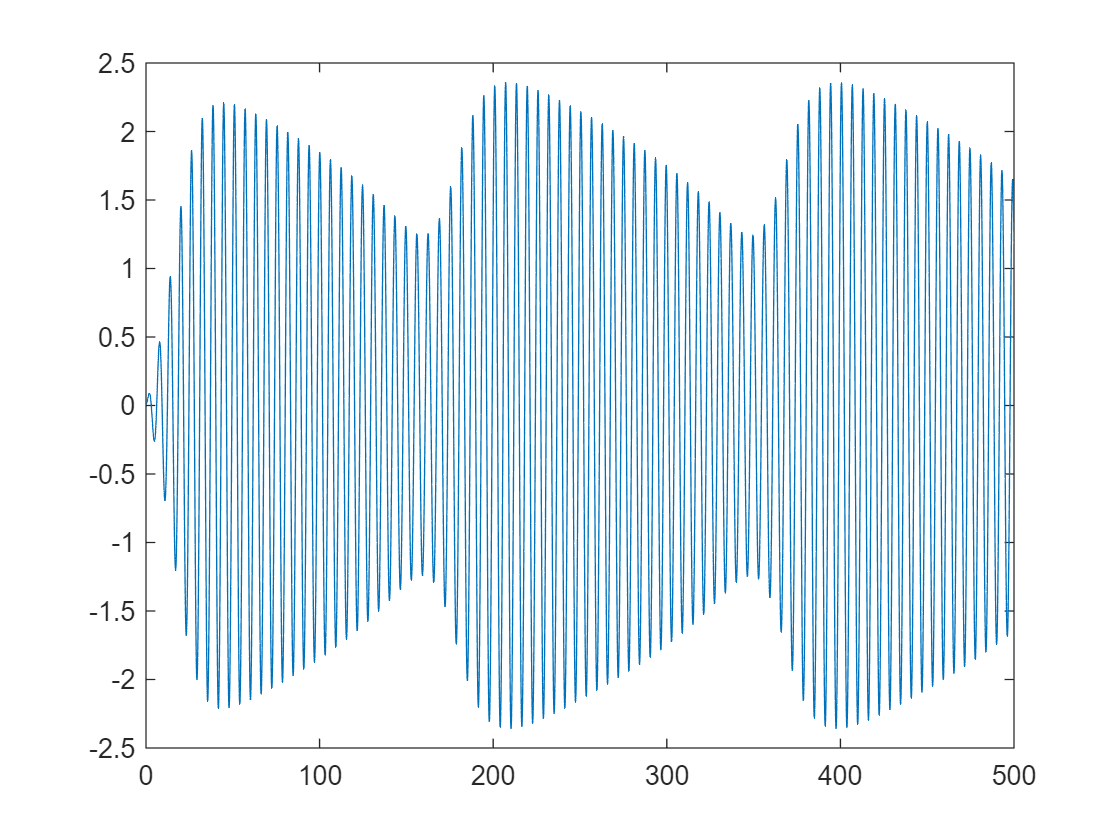

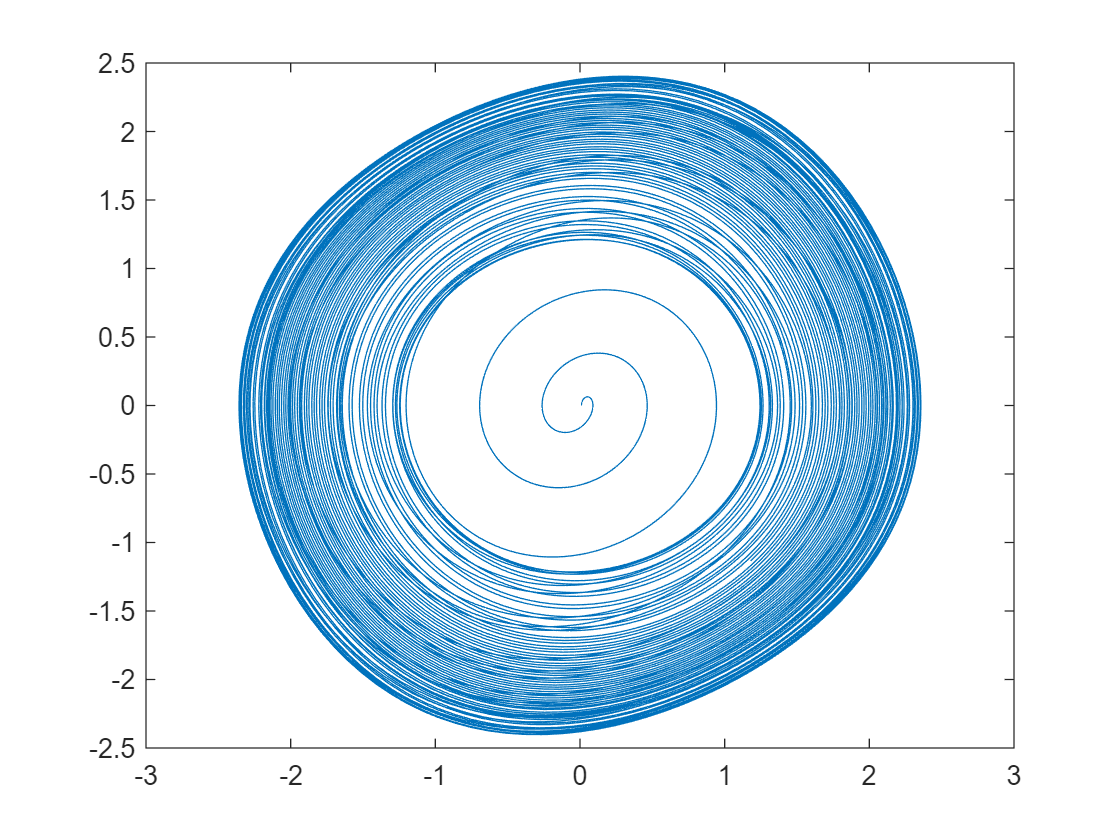

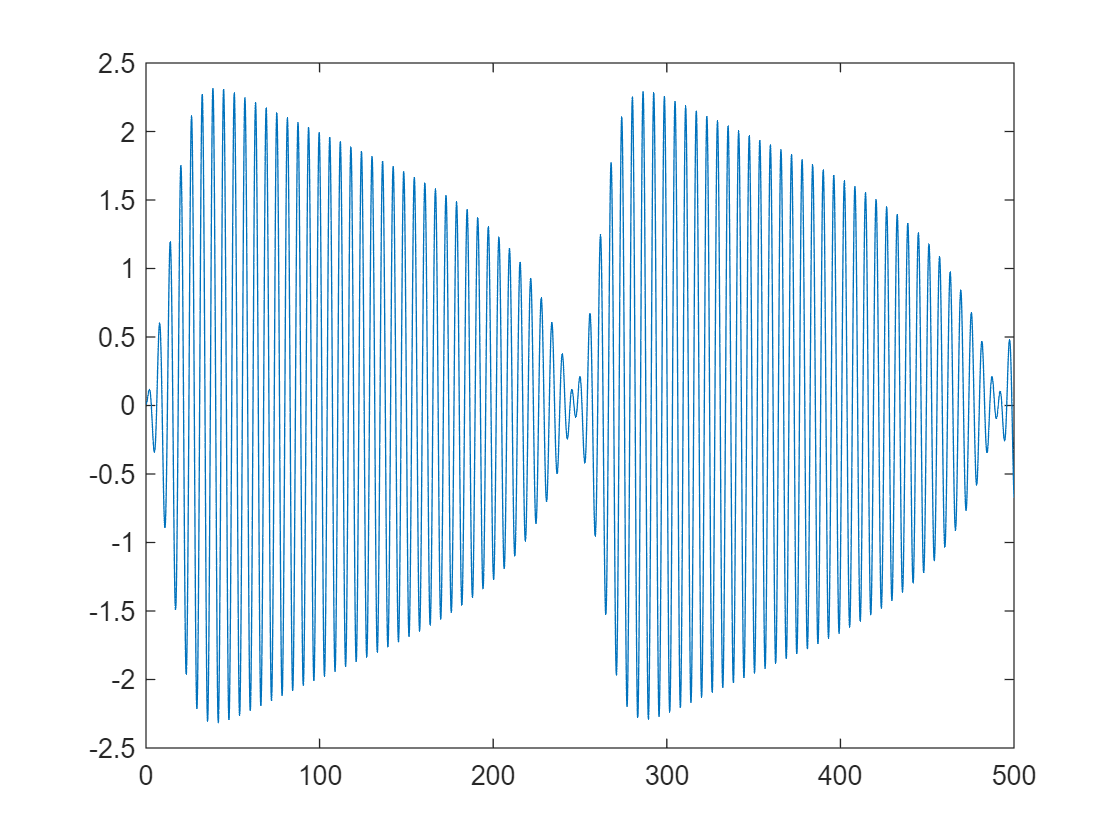

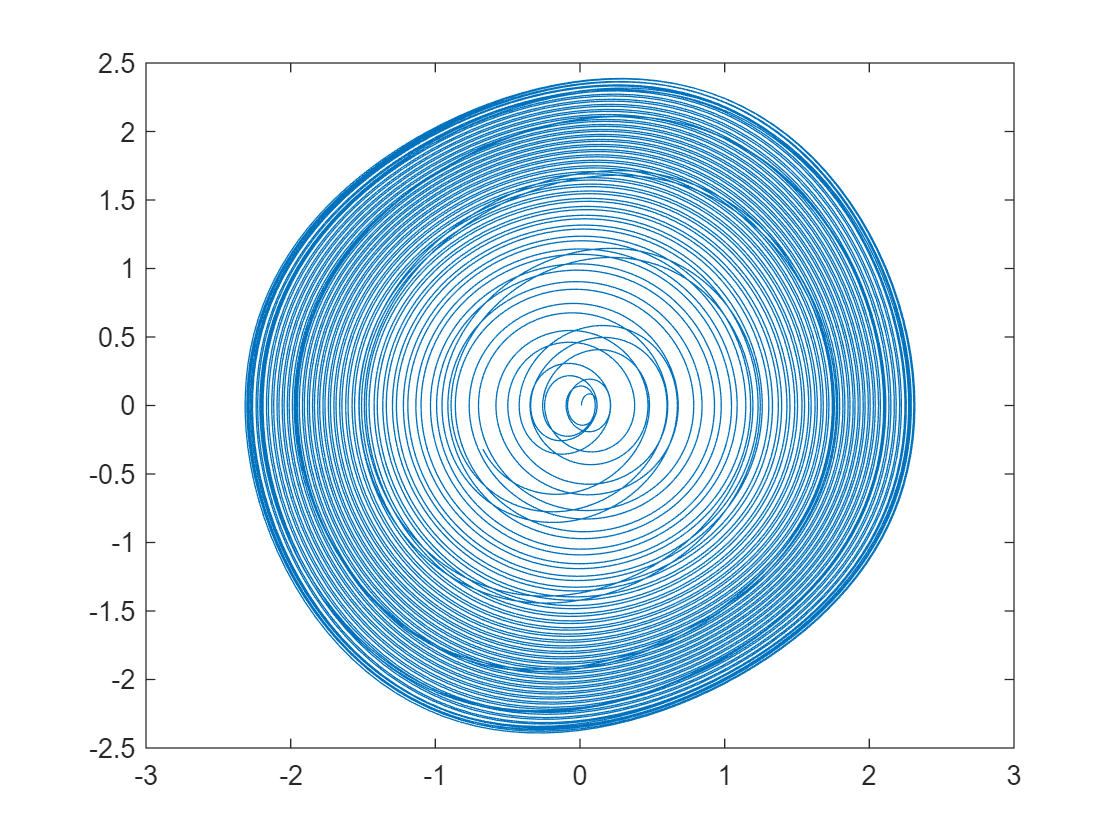

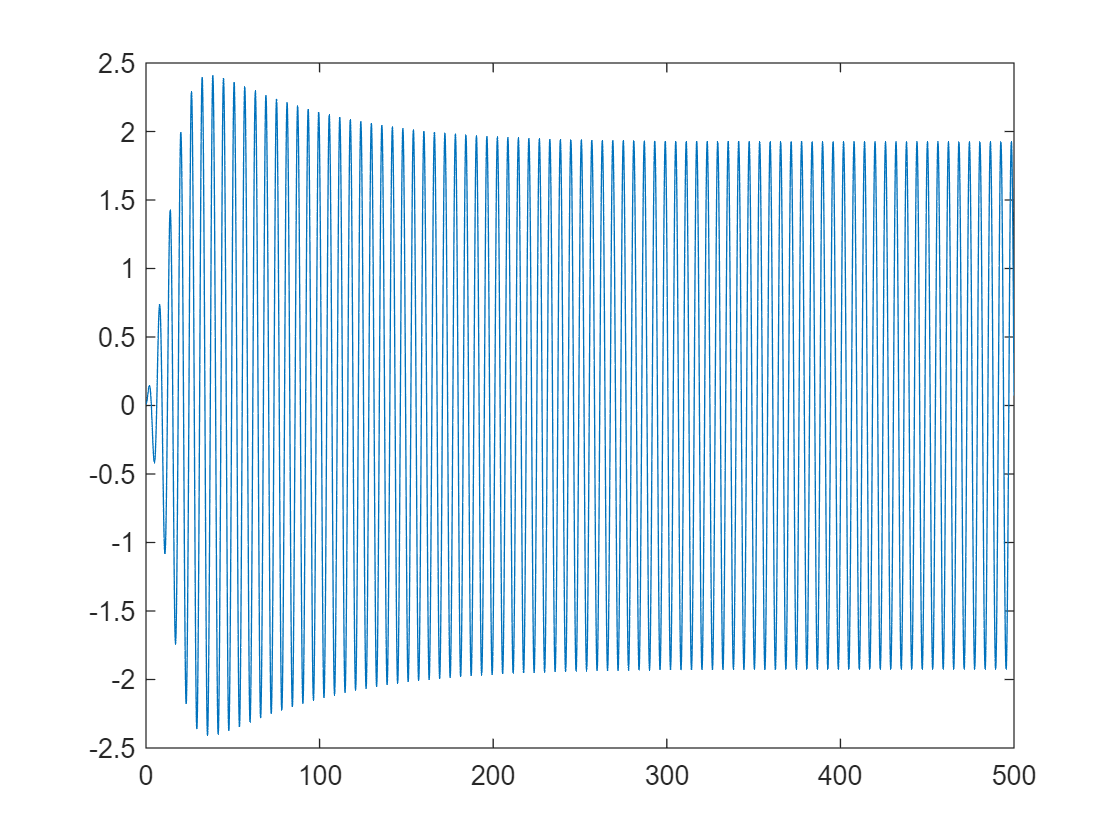

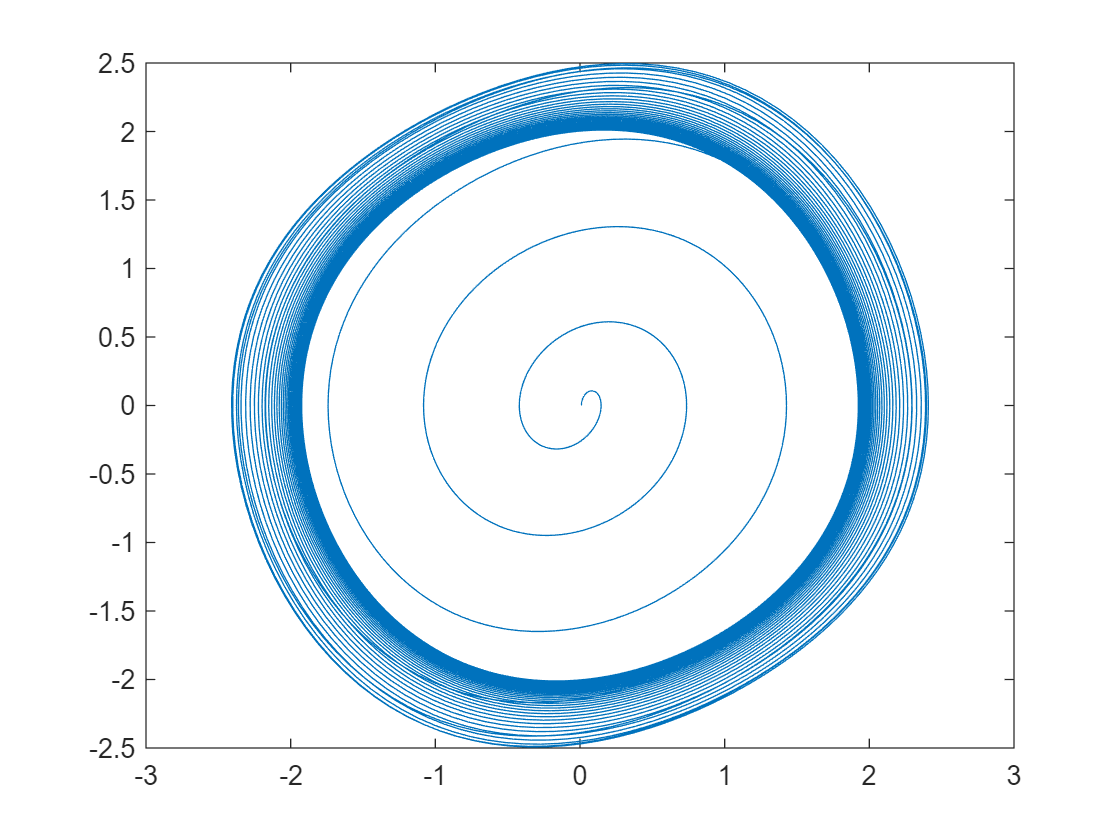

clear

%datos 
mu=0.1;
w=1.04;

%valores de a y b
a=0;
b=500;
h=0.05; %tamaño del paso
t=a:h:b;
N=(b-a)/h; %numero de pasos

x=zeros(2,N+1);
%los x iniciales x(1) es la posición y x(2) es la derivada
x(:,1)=[0.01;0];

% resolvemos el problema para cada valor de A
    % -mu*(x^2-1)*xp-x+A*cos(omega*t)  
%bucle para calcular las gráficas según los valores de A
A=[0.1,0.13,0.16];
for j=1:length(A)
    f=@(t,x) [x(2);-mu*(x(1)^2-1)*x(2)-x(1)+A(j)*cos(w*t)];
    
    for n=1:N
    
    k1=f(t(n)+1/4*h,x(:,n)+1/4*h*f(t(n),x(:,n))); %primera estimación de k1 con euler
    for i=1:200
        k1_viejo=k1;
        k1=f(t(n)+1/4*h,x(:,n)+1/4*h*k1);
        if abs(k1-k1_viejo)/abs(k1)<1e-4 %comprobamos que cometemos un error relativo menor
            break
        end
        if i==200
            fprintf('se ha alcanzado el numero maximo de pasos')
        end


    end

    %calculamos k2
    k2=f(t(n)+3/4*h,x(:,n)+1/4*h*f(t(n),x(:,n))); %primera estimación con euler
    for i=1:200
        k2_viejo=k2;
        k2=f(t(n)+3/4*h,x(:,n)+1/2*h*k1+1/4*h*k2);
        if abs(k2-k2_viejo)/abs(k2)<1e-4
            break
        end
        if i==200
            fprintf('se ha alcanzado el numero maximo de pasos')
        end

    end

    %la x
    x(:,n+1)=x(:,n)+h*0.5*(k1+k2);
    end
%graficamos
    figure
    plot(t,x(1,:))
    figure
    plot(t,x(1,:))
    figure
    plot(x(1,:),x(2,:))

end